# Tasks 2

## Quick refresher

Let's practice what we've already learned, but with a new dataset... The biopsies.csv dataset contains 569 examples of cancer biopsies from different patients. For each patient we have a series of numeric laboratory measurements, taken from a tissue biopsy, along with their true cancer diagnosis. You can assume the dataset is clean and ready for use in Machine Learning tasks. The aim is to automatically predict the diagnosis from the biopsy measurements. 

Work through the following steps to train and then evaluate a k-NN classifier on this new dataset (everything should be familiar from your previous work):

- Load up the biopsies.csv dataset into a Matlab cell array

- Delete the column headings from the first row and shuffle the remaining rows

- Perform your horizontal split (use 60% for training data and 40% for testing data)

- Separate out the class labels from the examples

- Pass your training examples and training labels to the `fitcknn()` function to train a model with k=1 (the default value)

- Pass your model and your testing examples to the `predict()` function to generate predictions

- Compare the predictions with the true training labels by computing a confusion matrix and use it to calcuate the overall classification accuracy

(**Sanity check**: You should get an overall classification accuracy of 93.4%)

% load a dataset compiled by someone else:
mycellarray = readcell('biopsies.csv');

% please leave this re-seeding of the random number generator in place so we can compare results
rng(0); 

% deletes title row
mycellarray(1:1:1, :) = [];

% shuffle cell array
shuffle = mycellarray(randperm(size(mycellarray, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

test_examples= shuffle(1:1:tempTest, :);
train_examples = shuffle(tempTest+1:1:end, :);

% make the class data into categroical

% changes the cell array to a numerical array
label_index = 1;

% <my comment removed>:

test_labels = categorical(test_examples(:, label_index));
test_examples = cell2mat(test_examples(:, 1:end~=label_index));

% <my comment removed>:
train_labels = categorical(train_examples(:, label_index));
train_examples = cell2mat(train_examples(:, 1:end~=label_index)); 

%kNN = fitcknn(train_examples,train_labels,"NumNeighbors",3)
kNN = knn_fit(train_examples,train_labels,3)

kNN = struct with fields:
         ClassNames: [2×1 categorical]
    NumObservations: 341
       NumNeighbors: 3
     train_examples: [341×30 double]
       train_labels: [341×1 categorical]


    
%predictions = predict(kNN,test_examples)
predictions = knn_predict(kNN,test_examples);
    
[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 95.1754


original = predictions;




## Hyperparameter investigation

Now complete a brief investigation into the best choice of the hyperparameter k (the number of neighbours). Write a simple for loop that repeats the model training (by calling `fitcknn()`) and evaluation steps (by calling `predict()` and then computing a confusion matrix and overall accuracy), using each of the following values for k: 1, 3, 5, 7, ..., 30, and storing the corresponding classification accuracies in an array. Make a plot of the k values (on the x-axis) against the corresponding accuracies (on the y-axis) and briefly note in a final comment the value of k you would select based on what you see:

(**Sanity check**: You should see overall classification accuracies as high as 96.9%)

%create a function var for the kNN trainer


grow = [];

for i=1:2:30

    kNN = fitcknn(train_examples,train_labels, 'NumNeighbors', i);
    predictions = predict(kNN,test_examples);
    
    
    [c, order] = confusionmat(test_labels, predictions);
    p = sum(diag(c)) / sum(c(1:1:end)) * 100;

    newc = [i,p];

    grow(end+1,:) = newc;

end

%finds the highest percentage accuracy for optimal K
acc = max(grow(:,2))

acc = 96.9298


%finds all K values with the same highest percentage
index1 = grow(:,2) == acc;


%this prevents unessary excess data and finds the optimal K

k = grow(index1,1);
%array of all K's with the highest percentages


k_best = round(size(k,2) \ 2);
%finds most optimal K which compinsates for over and underfitting by
%getting the mean of all of the Ks

k(k_best,:)

ans = 13

%displays optimal K




## Extension task: implementing k-NN classification with k=1

A great way to ensure you really understand k-NN classification is to implement it for yourself. The challenge here is to complete some provided function stubs in order to recreate the default behaviour of the `fitcknn()` function (k=1 nearest neighbour) and of calls to `predict()` with resulting models.... The steps below lead you through the process. Once you've finished, you should be able to reproduce the `fitcknn()` result you got in the first task (producing an identical confusion matrix and overall classifcation accuracy):

- Complete the `knn_fit()` function stub so that it stores the training data and the value of k inside the struct, `m`, and returns it (further guidance is available in the comments at the top of the file)

- Complete the `knn_calculate_distance()` function stub so that it returns the Euclidean distance, `d`, between any two points defined by the coordinates in the supplied arrays `p` and `q` (further guidance is available in the comments at the top of the file)

- Extend the `knn_predict()` function stub so that it uses the supplied k-NN model, `m`, to generate a prediction for each of the testing examples in the supplied array, `test_examples`, and returns the results in the array called `predictions` (for now you can assume k=1, always)

- In the code listing below, call on your new functions to evaluate the performance of a k-NN model with k=1 on the biopsies data you prepared earlier

(**Sanity check**: you should get an overall classification accuracy of 93.4% once again)


m = knn_fit(train_examples, train_labels,3);

predictions = categorical;

k = m.NumNeighbors;
train_examples = m.train_examples;

new= [];


for i=1:1:size(test_examples,1)
    for j=1:1:size(train_examples,1)

        q = train_examples(j,:);    
        p = test_examples(i,:);


        new(end+1,1) = knn_calculate_distance(p,q);
        %call Euclidean distance calculator 

        new(end,2) = j;
        %stores index at 2nd position
        
        if(j == size(train_examples,1))

              new = sortrows(new,1);
              %sorts array of Euclidean distance by smallest first 

              new = new([1:k],:);
              %collects sample of of sorted array of size k(usually 3)
              
              predictions(end+1,:) = mode(train_labels(new(:,2)));
              %store the mode of the distances or nearest neighbor

              new = [];
              %reset array helps with speed

         
        end
    end
end


    
[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 95.1754


%y(:,end+1) = 
%string(test_labels(:))




















## Extension task: varying k

Important: protect your earlier work if you attempt this extension task. Keep a copy of your completed `knn_fit()` and `knn_predict()` functions from the previous task just in case (they could get you credit on the assessment).

The challenge here is to rewrite your code from the previous task so that the caller of `knn_fit()` can set k (the number of neighbours being used) and then pass the resulting model to `knn_predict()` to make predictions with >1 nearest neighbours. For example, it should be possible for you to make the following calls:

- `m_knn3 = knn_fit(train_examples, train_labels, 3) % fit using k=3 nearest neighbours`

- `predictions = knn_predict(m_knn3, test_examples); % predict using k=3 nearest neighbours`

Once you've finished updating your two functions, you should be able to reproduce the best performance you saw in the second task (the k investigation). In the code listing below, call on your new functions to train a k-NN model on the training data you prepared earlier, and using the optimal k value you determined above. Then classify the testing data you prepared earlier and evaluate the model's performance:

(**Sanity check**: once again you should be able to produce an overall classification accuracy of 96.9%)


m_knn3 = knn_fit(train_examples, train_labels, k_best);

predictions = knn_predict(m_knn3, test_examples);

[c, order] = confusionmat(test_labels, predictions);

p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 95.1754

## Extension task: visualising feature space

Load up the iris data you worked with in the previous lab sheet and prepare it for use in machine learning tasks, setting aside 40% as testing data (you can copy/paste code from your previous live script, or see if you can remember the steps). Delete the 3rd and 4th columns of your training data to leave yourself with only sepal features for each iris (sepal length and sepal width). Now use `gscatter()` to visualise the resulting 2D feature space, with each training example represented by a single point that is colour coded by its associated class label:

(**Sanity check**: the "sepal-only feature space" is shown in the lecture slides if you want to compare against it)

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

mycellarray = readcell('iris.csv');

% deletes title row
mycellarray(1:1:1, :) = [];

% shuffle cell array
shuffle = mycellarray(randperm(size(mycellarray, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

shuffle(:,[3,4]) = []

shuffle = 150×3 cell array
    {[7.7000]}    {[2.8000]}    {'virginica' }
    {[5.1000]}    {[2.5000]}    {'versicolor'}
    {[5.4000]}    {[3.4000]}    {'setosa'    }
    {[5.1000]}    {[3.4000]}    {'setosa'    }
    {[5.1000]}    {[3.7000]}    {'setosa'    }
    {[5.5000]}    {[4.2000]}    {'setosa'    }
    {[6.1000]}    {[     3]}    {'versicolor'}
    {[5.5000]}    {[2.6000]}    {'versicolor'}
    {[6.7000]}    {[     3]}    {'virginica' }
    {[7.7000]}    {[2.6000]}    {'virginica' }
    {[6.4000]}    {[2.7000]}    {'virginica' }
    {[6.2000]}    {[2.8000]}    {'virginica' }
    {[4.9000]}    {[3.1000]}    {'setosa'    }
    {[5.4000]}    {[3.9000]}    {'setosa'    }
    {[6.9000]}    {[3.2000]}    {'virginica' }
    {[6.5000]}    {[2.8000]}    {'versicolor'}



test_examples = shuffle(1:1:tempTest, :);
train_examples = shuffle(tempTest+1:1:end, :)

train_examples = 90×3 cell array
    {[5.2000]}    {[3.5000]}    {'setosa'    }
    {[6.1000]}    {[     3]}    {'virginica' }
    {[6.7000]}    {[3.3000]}    {'virginica' }
    {[5.4000]}    {[3.9000]}    {'setosa'    }
    {[7.4000]}    {[2.8000]}    {'virginica' }
    {[     5]}    {[3.5000]}    {'setosa'    }
    {[     6]}    {[2.2000]}    {'virginica' }
    {[5.1000]}    {[3.8000]}    {'setosa'    }
    {[6.5000]}    {[3.2000]}    {'virginica' }
    {[6.2000]}    {[2.9000]}    {'versicolor'}
    {[5.7000]}    {[2.6000]}    {'versicolor'}
    {[4.3000]}    {[     3]}    {'setosa'    }
    {[4.8000]}    {[     3]}    {'setosa'    }
    {[5.7000]}    {[2.8000]}    {'versicolor'}
    {[     6]}    {[2.2000]}    {'versicolor'}
    {[6.8000]}    {[3.2000]}    {'virginica' }



label_index = 3;

test_labels = categorical(test_examples(:, label_index));
test_examples = cell2mat(test_examples(:, 1:end~=label_index));

train_labels = categorical(train_examples(:, label_index));
train_examples = cell2mat(train_examples(:, 1:end~=label_index));




% index_example = trainData;
% 
% for i=1:1:size(trainData)
%     index_example(i,3) = i;
% end
% index_example
% 
% index_example = [string(trainCategorical) index_example]
% 
% index_example = sort(index_example,1)
% 
% labels = unique(string(trainCategorical));
% 
% r1 = index_example(labels(1) == index_example,2);
% r2 = index_example(labels(2) == index_example,2);
% r3 = index_example(labels(3) == index_example,2);
% 
% r1 = double(r1);
% r2 = double(r2);
% r3 = double(r3);
% 
% L = trainData(:,1);
% maxVal = max(L)
% minVal = min(L)
% range = (maxVal-minVal);
% jmpSz = range/80;
% 
% 
% L = [];
% 
% row=0;
% col=0;
% cat = [];
% cat = string(cat);
% 
% 
% for i=minVal:jmpSz:maxVal
%     for j=minVal:jmpSz:maxVal
%         L(end+1,:) = i;
% 
%         if(i >= min(r1)) && (i <= max(r1+0.05))
%             cat(end+1) = labels(1);
%         elseif(i >= min(r2-0.04)) && (i <= max(r2))
%             cat(end+1) = labels(2);
%         elseif(i >= min(r3)) && (i <= max(r3))
%             cat(end+1) = labels(3);
% 
%         end
%     end
% end
% cat = reshape(cat,[size(cat,2),1]);
% L
% 
% W = trainData(:,2);
% 
% 
% 
% maxVal = max(W);
% minVal = min(W);
% range = (maxVal-minVal);
% jmpSz = range/80;
% 
% W =[];
% 
% for i=minVal:jmpSz:maxVal
%     for j=minVal:jmpSz:maxVal
%         W(end+1,:) = i;
%     end
% end
% 
% test = [L W]
% 
% 
% 
% size(L,1)
% 
% %A = repmat(trainCategorical,80,1);
% 
% %A=A(1:size(L,1));
% 
% %j = classify([L W],cat);
% 
% 
% gscatter(L,W,cat)

%---------------------------


%j = classify([length width],testData(:,1:2),testCategorical);

%gscatter(length,width,j,'rgb')

## Extension task: visualising abstractions

Again working in the sepal-only feature space, using the training data you generated in the previous task, can you generate a visualisation of the abstraction produced by the k-NN classifier using k=1? Use your code to look at the abstractions produced with some higher k values, e.g.: k = 2, 4, 8, 16, 32, 64. Finally try with k equal to the total number of training examples minus 1 (the maximum number of nearest neighbours it is possible to consider).

(**Sanity check**: the abstractions are shown at the end of the lecture slides if you want to compare against them)

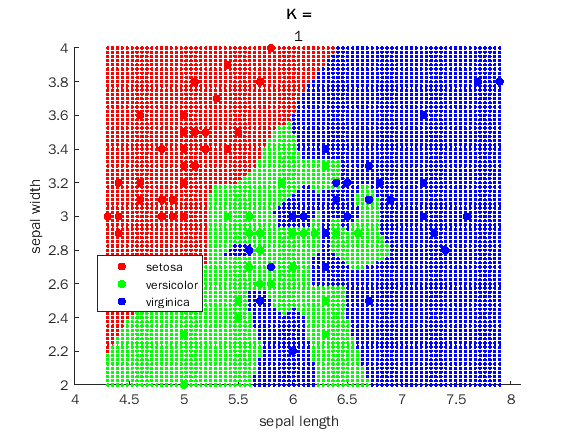

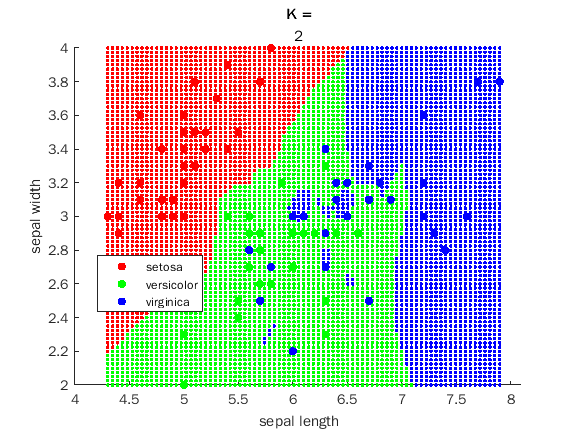

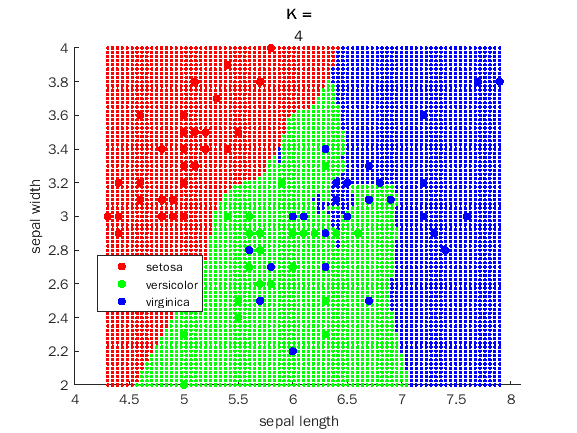

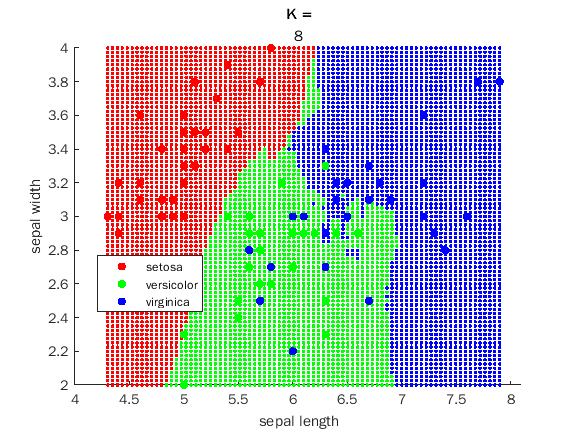

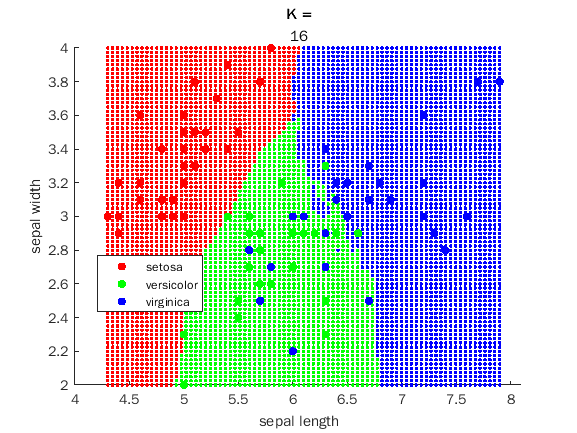

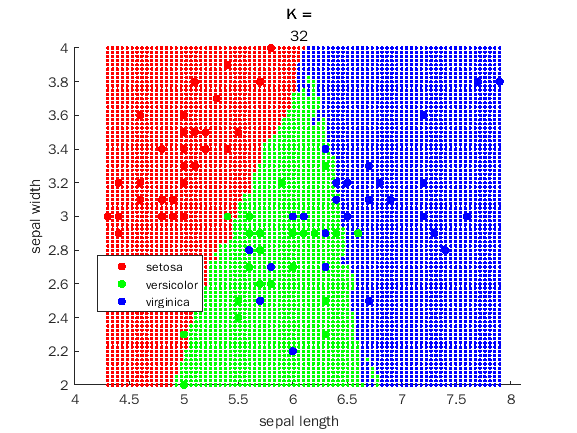

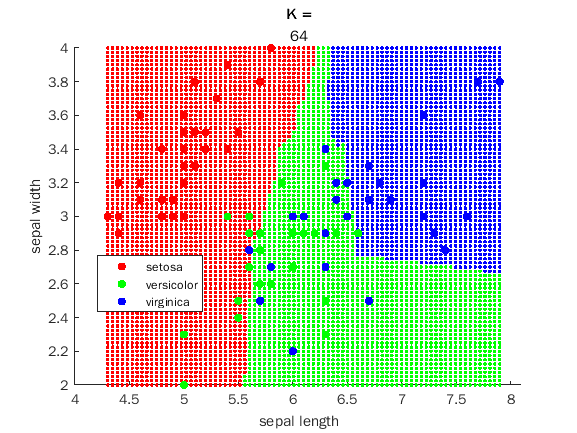

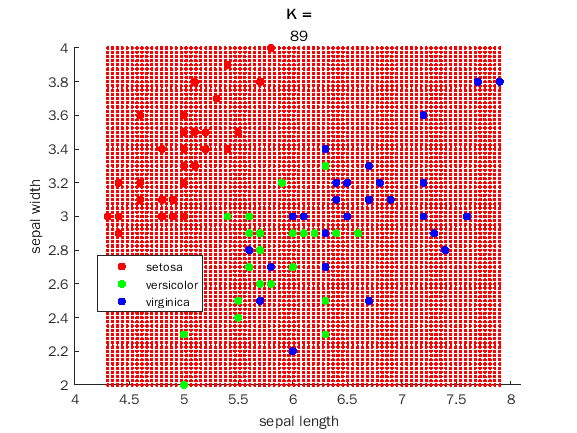


%https://uk.mathworks.com/help/stats/classification-example.html
%ideas from this as i was struggling to create the grid of data using loops

maxK = size(train_examples,1) -1;
%finds maxiumum K value -1 to get the highest K possible

maxLenVal = max(train_examples(:,1));
minLenVal = min(train_examples(:,1));
%takes the min and max value for incrmenting

rangeLen = (maxLenVal - minLenVal) / 80;
%calculating the range for incrementing the grid array


maxWdthVal = max(train_examples(:,2));
minWdthVal = min(train_examples(:,2));

rangeWth = (maxWdthVal - minWdthVal) / 80;


for i=[1 2 4 8 16 32 64 maxK]
    %K value loop

    kNN = fitcknn(train_examples,train_labels, 'NumNeighbors', i);

    
    length = minLenVal:rangeLen:maxLenVal;
    width = minWdthVal:rangeWth:maxWdthVal;
    %easier this way than for loop as no other data is needed
    %technically same as a for loop without the extra code i.e min val increment
    %and max value

    [x, y] = meshgrid(length,width);
    %meshgrid function creates a grid the length and width of both being equal to
    %the inputs
    %NOTE: X is duplicated vertically and Y is duped horizontailly

    test_examples = [x(:) y(:)];
    %new test examples are created to be the same dimensions as the orginal
    %test_examples as a contactinated 1d array

    
    prediction = predict(kNN,test_examples);
    
    figure();
    hold on
    gscatter(x(:), y(:),prediction,'rgb')
    gscatter(train_examples(:,1), train_examples(:,2),train_labels)
    %layered the original data over the grid of points
    xlabel('sepal length')
    ylabel('sepal width')
    title('K =',i)
    

end